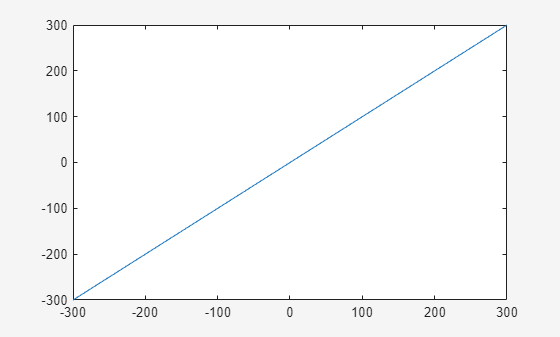

clear all

z = -450;

% pick points
numPoints = 3;
plot(-300:300,-300:300);
hold on
[xp, yp] = ginput(numPoints);


cla
plot3(xp, yp, z*ones(numPoints,1), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
xlim([-400 400]);ylim([-400 400])
%hold off

EndPosn = [xp, yp, z*ones(numPoints,1)]

EndPosn =    55.9908  161.4545 -450.0000
  -93.3180  -10.9091 -450.0000
  191.4747  -89.4545 -450.0000


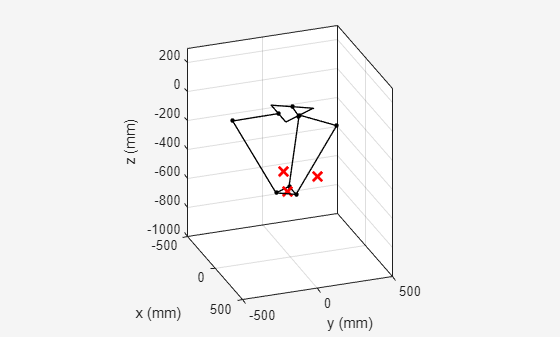

Invalid or deleted object.

Error in Animate (line 35)
        Arm1_plot.XData = Arm1(tx).XData;
        ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^




% get IK solns
for index = 1:numPoints
    [theta1(index), theta2(index), theta3(index), valid(index)] = IK(EndPosn(index,:));
end
theta1;
[theta1,theta2,theta3,valid];

q1 = [theta1(1)]; q2 = [theta2(1)]; q3 = [theta3(1)];

num = 50;

% make vectors between bottles:
for index = 2:numPoints
  q1 = [q1,linspace(theta1(index-1),theta1(index),num)];
  q2 = [q2,linspace(theta2(index-1),theta2(index),num)];
  q3 = [q3,linspace(theta3(index-1),theta3(index),num)];
end


Q1 = flip(q1);
Q2 = flip(q2);
Q3 = flip(q3);

for index = 1:50
    Animate(q1,q2,q3);
    Animate(Q1,Q2,Q3);
end